# Homework 1 - Risk Management

clc
clear all
close all
perc_cover = [0,0.25,0.5,0.75,1];
perc_forward = [0,0.25,0.5,0.75,1];
change = [1.01,1.22,1.48];
volume = [10000,25000,30000];
K = 1.22;

%la politica è stabile su 25000 studenti
volume_policy = 25000;

format bank
impact = hedging_policies(perc_cover, perc_forward, change, volume, volume_policy, K);
%print impact di un caso particolare
%impact()
minMatrix = squeeze(min(min(impact,[],1),[],3));
disp(array2table(minMatrix,'VariableNames',cellstr(num2str(perc_forward')),...
                           'RowNames',cellstr(num2str(perc_cover'))));

                 0        0.25         0.5        0.75           1  
            ________    ________    ________    ________    ________

    0       -7800.00    -7800.00    -7800.00    -7800.00    -7800.00
    0.25    -6556.25    -6460.94    -6365.63    -6270.31    -6175.00
    0.5     -5312.50    -5121.88    -4931.25    -4740.63    -4550.00
    0.75    -4068.75    -3782.81    -3496.88    -3210.94    -2925.00
    1       -2825.00    -2443.75    -2062.50    -2218.75    -3150.00



Valori bassi perché cambio irrealistico a 1.48 penalizza molto

maxOfMatrix(minMatrix, perc_cover, perc_forward)

max:		-2062.5
perc_cover:	1
perc_forward:	0.5


### Dati reali

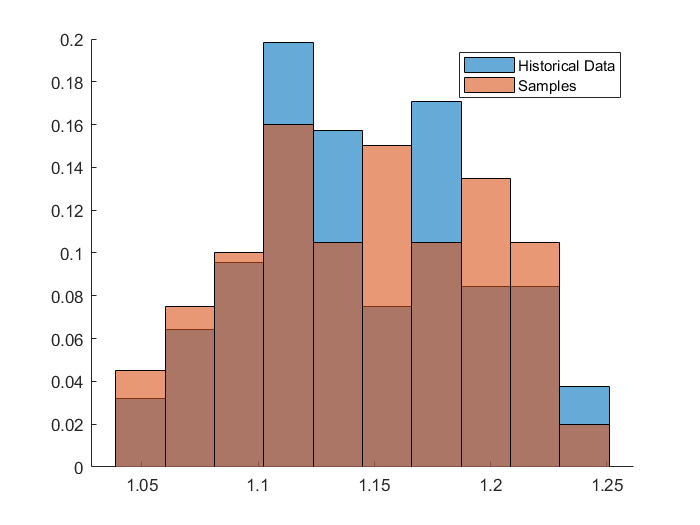

samplesChange = samplingBetaFromData(true);

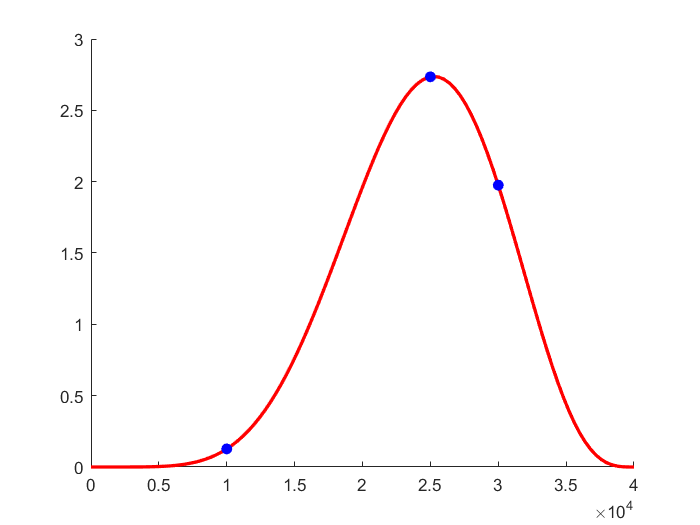

samplesVolume = samplingBetaFromParameter(7,4.5,0,40000,true,volume);

impact = hedging_policies(perc_cover, perc_forward, samplesChange, samplesVolume, volume_policy, K);

probabilities = [0.9 0.95 0.99];

### Historical Simulation

[minMatrix, varianza, deviazione_standard, VaR, CVar]=RiskMeasures(probabilities, impact, 'Historical Simulation');
squeeze(VaR(3,:,:))

ans =        -381.92       -381.92       -381.92       -381.92       -381.92
       -664.62       -569.31       -474.00       -378.68       -283.37
       -953.55       -762.92       -572.30       -381.67       -243.70
      -1249.41       -963.47       -677.53       -536.43       -752.81
      -1553.77      -1172.52       -890.75      -1134.06      -1596.43


maxOfMatrix(squeeze(VaR(3,:,:)), perc_cover, perc_forward)

max:		-243.6988
perc_cover:	0.5
perc_forward:	1


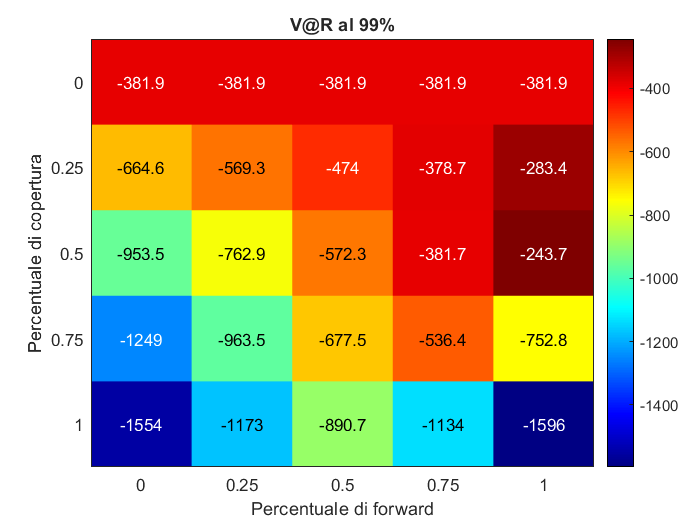

heatmap(perc_cover, perc_forward,squeeze(VaR(3,:,:)),'Title','V@R al 99%', ...
    'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
    'GridVisible','off','Colormap',jet);

### Parametric Beta

[minMatrix, varianza, deviazione_standard, VaR, CVar]=RiskMeasures(probabilities, impact, 'Parametric Beta');
squeeze(VaR(3,:,:))

ans =        -406.03       -406.03       -406.03       -406.03       -406.03
       -719.31       -628.43       -538.18       -448.69       -360.16
      -1028.10       -848.51       -671.89       -499.74       -334.15
      -1331.91      -1064.97       -805.32       -760.71       -763.43
      -1630.20      -1275.89      -1088.45      -1138.00      -1203.91


maxOfMatrix(squeeze(VaR(3,:,:)), perc_cover, perc_forward)

max:		-334.1471
perc_cover:	0.5
perc_forward:	1


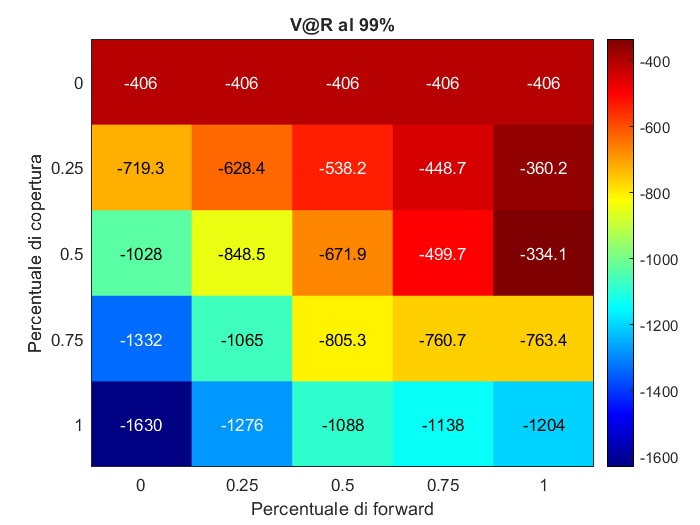

heatmap(perc_cover, perc_forward,squeeze(VaR(3,:,:)),'Title','V@R al 99%', ...
    'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
    'GridVisible','off','Colormap',jet);

### Parametric Normal

[minMatrix, varianza, deviazione_standard, VaR, CVar]=RiskMeasures(probabilities, impact, 'Parametric Normal');

Normale non va bene perché le code che hanno valori irrealistici pesano troppo nel calcolo dei valori, ad esempio confrontiamo il V@R della normale parametrica in confronto a quella dei dati originali

squeeze(VaR(3,:,:))

ans =       -1244.85      -1244.85      -1244.85      -1244.85      -1244.85
      -1611.15      -1468.19      -1327.09      -1188.24      -1052.08
      -1977.86      -1693.92      -1419.10      -1157.64       -916.46
      -2344.99      -1922.56      -1525.60      -1175.91       -919.33
      -2712.53      -2154.74      -1654.43      -1291.85      -1239.93


## Dati reali ma con più "politiche"

perc_cover = [0:0.01:1];
perc_forward = [0:0.01:1];
impact = hedging_policies(perc_cover, perc_forward, samplesChange, samplesVolume, volume_policy, K);
[minMatrix, varianza, deviazione_standard, VaR, CVar]=RiskMeasures(probabilities, impact, 'Historical Simulation');
squeeze(VaR(3,:,:))

ans =        -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92       -381.92
       -392.92       -392.76       -392.61       -392.46       -392.31       -392.15       -392.00       -391.85       -391.70       -391.54       -391.39       -391.24       -391.09       -390.93       -390.78       -390.63       -390.48       -390.32       -390.17       -390.02       -389.8

maxOfMatrix(squeeze(VaR(3,:,:)), perc_cover, perc_forward)

max:		-211.2287
perc_cover:	0.45
perc_forward:	1


maxOfMatrix(squeeze(VaR(2,:,:)), perc_cover, perc_forward)

max:		-21.7217
perc_cover:	0.4
perc_forward:	1


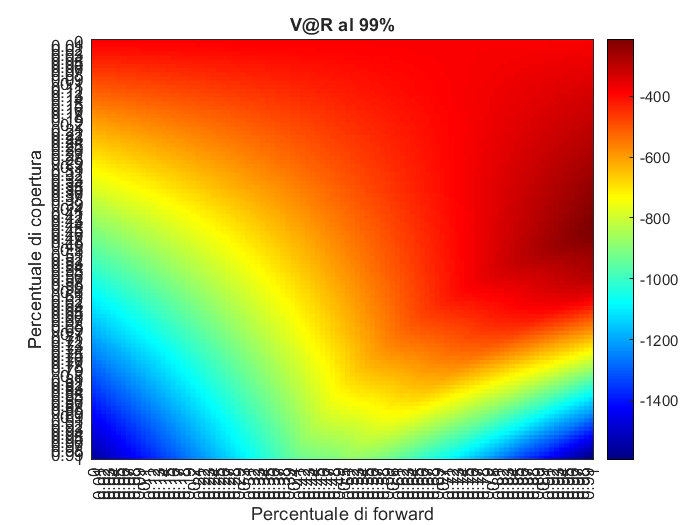

heatmap(perc_cover,perc_forward,squeeze(VaR(3,:,:)),'Title','V@R al 99%', ...
    'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
    'GridVisible','off','Colormap',jet);

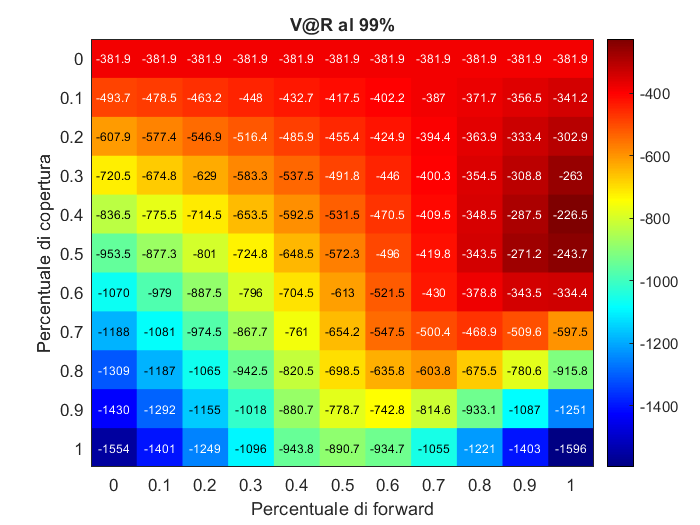

heatmap(perc_cover(1:10:101),perc_forward(1:10:101),squeeze(VaR(3,1:10:101,1:10:101)),'Title','V@R al 99%', ...
    'XLabel','Percentuale di forward','YLabel','Percentuale di copertura', ...
    'GridVisible','off','Colormap',jet);